# Symbolic Math ToolBox

Provides functions for solving, plotting and manipulating symbolic maths equations

- Ordinary Differntial Equation

- Equation Simplification

- Calculus

- Equation Manipulation

- Linear Algebra

Results displayed in **Mathematical Typeset** : 

syms x
eq = sqrt(x+3/10) == 0

$$eq = \sqrt{x+\frac{3}{10}}=0$$

# Simple 2D Graphs

## Simple Graphs: Functions of a single real variable

**    Q. To plot **$\mathrm{sin}\left(\frac{10}{\left(1+x^2 \right)}\right)$

syms x
f = sin(10/(1+x^2))

$$f = \sin\left(\frac{10}{x^{2}+1}\right)$$

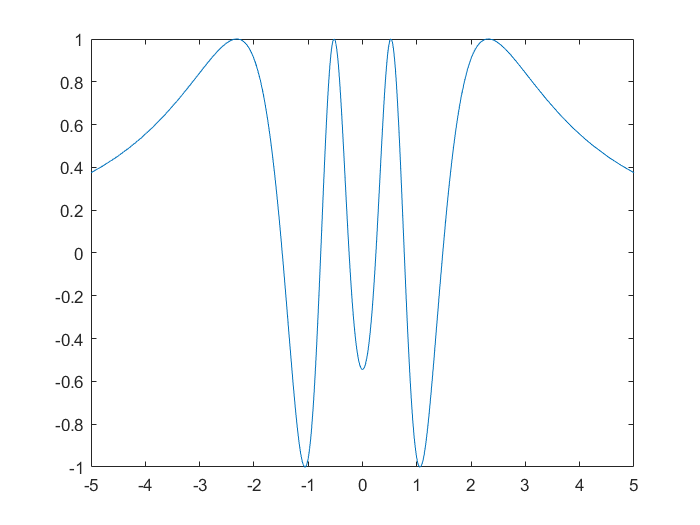

fplot(f)

**Default range of x is [-5,5]. To override:**

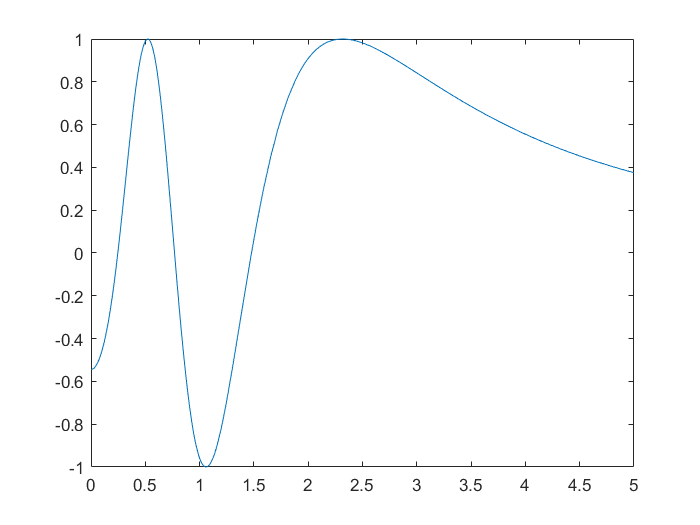

fplot(f,[0,5])

**Q. Draw graphs of many functions in the same plot.**

syms x
fplot( [sin(x) cos(x)], [-2*pi 2*pi])
legend show
title('sin(x) and cos(x) from -2*pi to 2*pi')
% To modify the properties of the graph

ax = gca

ax =   Axes (sin(x) and cos(x) from -2*pi to 2*pi) with properties:

             XLim: [-6.2832 6.2832]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


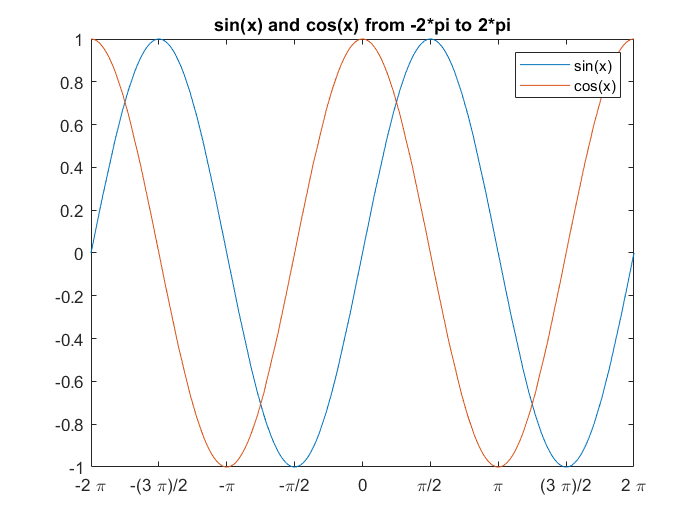

S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel, S, 'UniformOutput', 0);

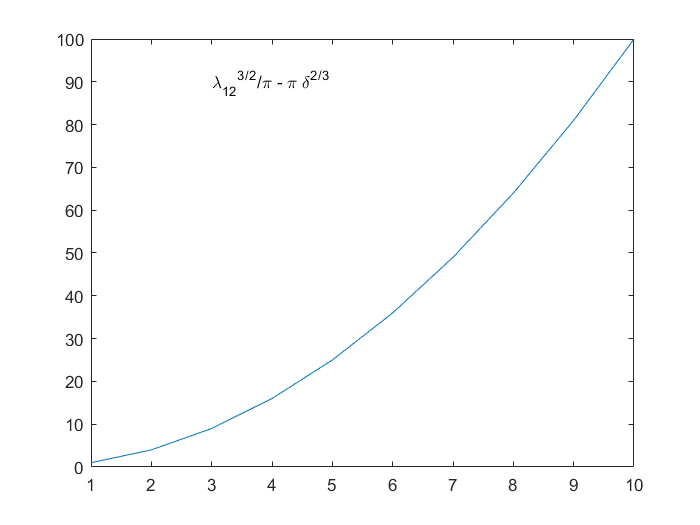

plot((1:10).^2)
txt = texlabel('lambda12^(3/2)/pi - pi*delta^(2/3)');
text(3,90,txt)

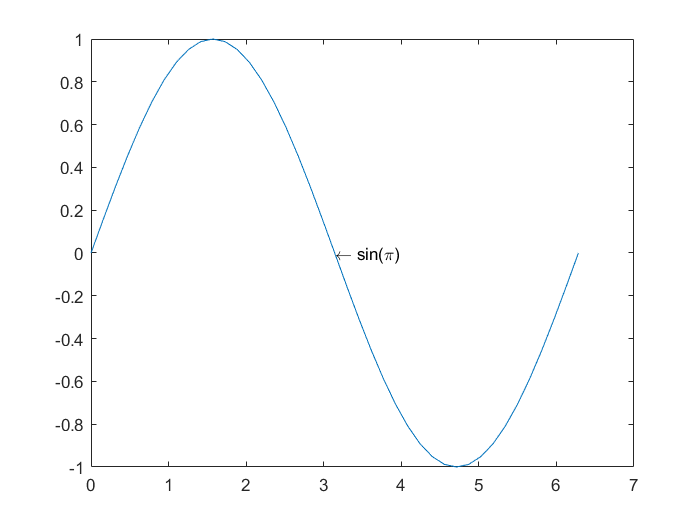

x = 0:pi/20:2*pi;
y = sin(x);
plot(x,y)
text(pi,0,'\leftarrow sin(\pi)')

# Parametric Plots

## **Q. Plot an ellipse given by **$\mathit{\mathbf{x}}=2\;\mathbf{cos}\left(\mathit{\mathbf{t}}\right)$ and $\mathit{\mathbf{y}}=\mathbf{sin}\left(\mathit{\mathbf{t}}\right)$**.**

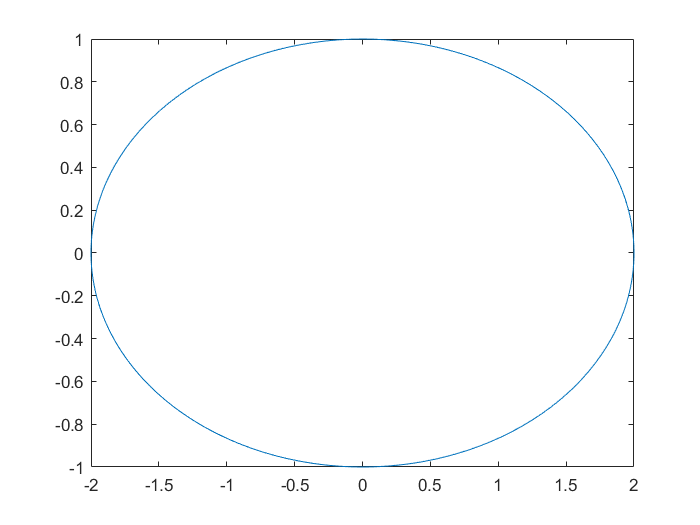

syms x y t
x = 2*cos(t);
y = sin(t);
fplot(x,y);

**Q. Plot a hyperbola.**

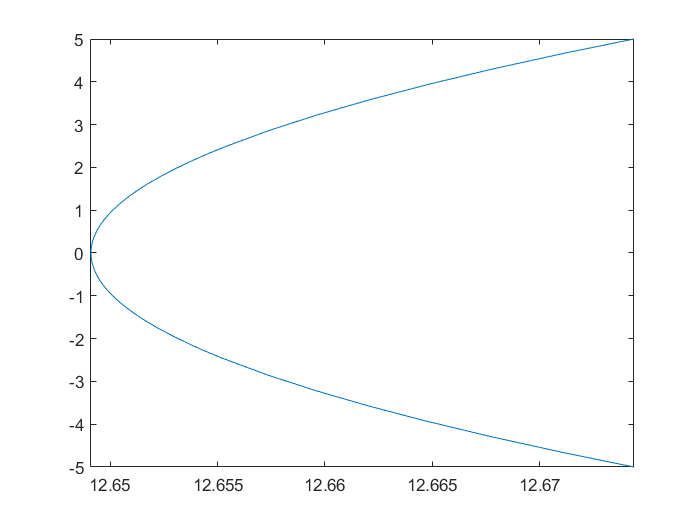

syms x y
x = t;
y = 4*sqrt(10+(t/25)^2);
fplot(y,x);

# Polar Plots

## Q. Plot a left-leafed horizontal cardioid.

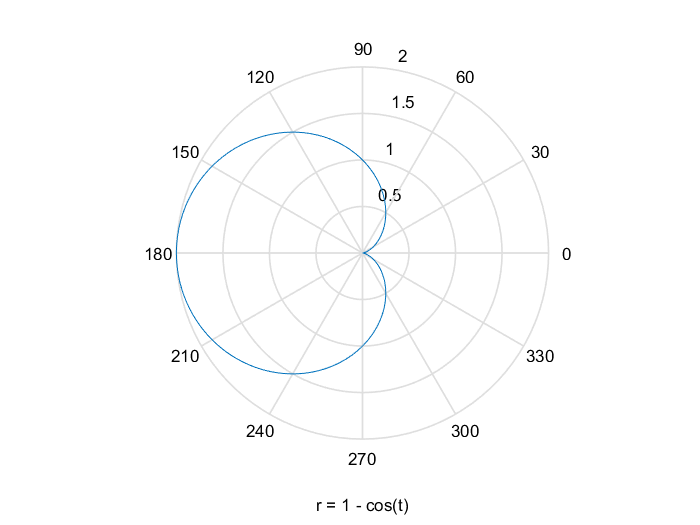

syms t
ezpolar(1-cos(t), [0 2*pi])

# 2D Visualization of Functions

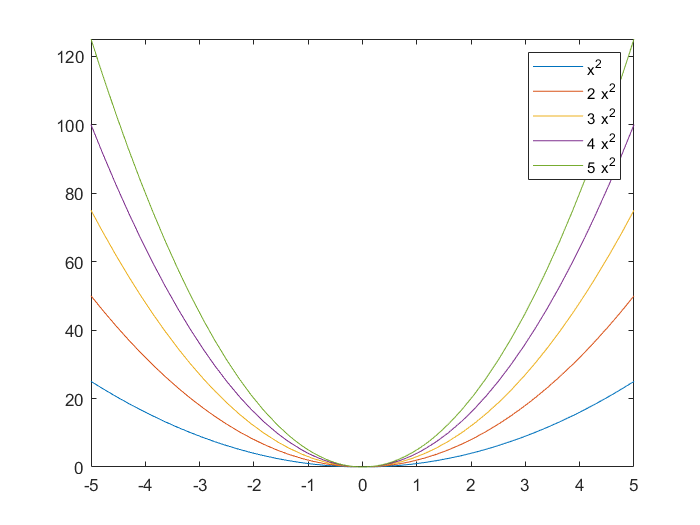

syms x
axis([-5 5 0 150])
for a=1:5
    fplot(a*x^2)
    hold on
end
hold off
legend show